%Transistor Parameters
%Freq=2.393675GHz
clc
disp(['Transistor Parameters'])

Transistor Parameters


s11dBmag=-2.86;
s11dBph=-108.74;
s12dBmag=-25.24;
s12dBph=26.54;
s21dBmag=15.58;
s21dBph=91.14;
s22dBmag=-3.21;
s22dBph=-52.01;

s11 = 10^(s11dBmag/20)*exp(s11dBph/180 * pi* 1i); % Convert from dB to linear scale
s12 = 10^(s12dBmag/20)*exp(s12dBph/180 * pi * 1i);
s21 = 10^(s21dBmag/20)*exp(s21dBph/180 * pi * 1i);
s22 = 10^(s22dBmag/20)*exp(s22dBph/180 * pi * 1i);

disp(['s11 = ', num2str(abs(s11)), '<', num2str(angle(s11)*180/pi)])

s11 = 0.71945<-108.74


disp(['s12 = ', num2str(abs(s12)), '<', num2str(angle(s12)*180/pi)])

s12 = 0.054702<26.54


disp(['s21 = ', num2str(abs(s21)), '<', num2str(angle(s21)*180/pi)])

s21 = 6.0117<91.14


disp(['s22 = ', num2str(abs(s22)), '<', num2str(angle(s22)*180/pi)])

s22 = 0.69103<-52.01



delta = ((s11*s22) - (s12 * s21)) %complex

delta = -0.3166 - 0.4551i

k = (1 - abs(s11*s11) - abs(s22 * s22) + abs(delta * delta))/(2 * abs(s12*s21));

%Unilateral Design Check
disp(['Unilateral design considerations'])

Unilateral design considerations


GTU = 15;
U = (abs(s12*s21*s11*s22))/((1-abs(s11^2))*(1-abs(s22^2)));

MD = 1/(1+U)^2;
LD = 1/(1-U)^2;

MDdB = 10*log10(MD);
LDdB = 10*log10(LD);

Lessval = (MDdB/GTU)*100

Lessval = -28.9519

Plusval = (LDdB/GTU)*100

Plusval = 60.5745

%Stability Considerations
%For Output Stability
disp(['Stability Considerations'])

Stability Considerations


Cout = (conj(s22 - conj(s11)*delta))/ (abs(s22 * s22) - abs(delta * delta));
Coutmag = abs(Cout)

Coutmag = 2.5633

Coutph = angle(Cout)*180/pi

Coutph = 84.4625

Coutc = [(real(Cout)), (imag(Cout))]

Coutc =     0.2473    2.5513



rout = abs(s12 * s21)/ ( abs(abs(s22 * s22) - abs(delta * delta)))

rout = 1.9327


%For Input Stability
Cin = (conj(s11 - conj(s22)*delta))/ (abs(s11 * s11) - abs(delta * delta));
Cinmag = abs(Cin)

Cinmag = 2.2209

Cinph = angle(Cin)*180/pi

Cinph = 137.5217

Cinc = [real(Cin), imag(Cin)]

Cinc =    -1.6380    1.4998



rin = abs(s12 * s21)/ ( abs(abs(s11 * s11) - abs(delta * delta)))

rin = 1.5643

%Available Power Gain Method
disp(['Available Power Gain Method'])

Available Power Gain Method


GAdB = 15; %Target gain in dB
GA = 10^(GAdB/10); %Target gain in linear scale

ga = GA/(abs(s21))^2;
dga = (ga*conj(s11-(delta*conj(s22))))/(1+(ga*(abs(s11*s11)-abs(delta*delta))));

dgac = [real(dga), imag(dga)]

dgac =    -0.2545    0.2330



numrga = sqrt(1-(2*k*ga*abs(s12*s21))+(ga*ga*(abs(s12*s21))^2));
denrga = abs(1+(ga*(abs(s11*s11)-abs(delta*delta))));

disp(['dga = ', num2str(abs(dga)), '<', num2str(angle(dga)*180/pi)])

dga = 0.34505<137.5217


rga = numrga/denrga

rga = 0.7600

% %maximum Power Gain
% disp(['Maximum Power Gain Method'])
% %Gamma s parameters
% C1 = s11- (conj(s22) * delta)
% B1 = 1 + abs(s11 * s11) - abs(s22 * s22) - abs(delta * delta)
% 
% Gs = (B1/(2* C1)) - (0.5 * sqrt(((B1/C1)*(B1/C1)) - (4 * (conj(C1)/C1))))
% 
% 
% %Gamma L parameters
% C2 = s22 - (conj(s11) * delta)
% B2 = 1 + abs(s11 * s11) + abs(s22 * s22) - abs(delta * delta)
% 
% GL = (B2/(2*C2)) - (0.5 * sqrt(((B2/C2)*(B2/C2)) - (4 * (conj(C2)/C2))))
% 
% %Gamma in and Gamma out calculation
% %still fix formuli
% Gin = s11 + ((s21 * s12 * GL )/(1 - s22 * GL))
% Gout = s22 + ((s21 * s12 * Gs )/(1 - s11 * Gs))
% X = abs(Gs)
% GTnum = (1 - (abs(Gs) * abs(Gs))) * abs(s21)*abs(s21) *(1-abs(GL * GL))
% GTden = (abs( (1- (s11 * Gs)) * (1-(s22 * GL)) - (s12 * s21 * GL * Gs) ))
% GTd = GTden * GTden;
% GT = GTnum/GTd
% 
% %Should be GT but like S  parameters who?
% %Transducer Gain

%Noise Figure Code

Goptmag = 0.745;
Goptph = 65;
Gopt = 10^(Goptmag/20)*exp(Goptph/180 * pi* 1i);
Fmin = 10*exp(0.39/10); %dB
Rn = 8;   %this gets divided by 50 to become 0.16
Zo = 50;

F = Fmin + (4 * Rn / Zo) * (abs((Gs-Gopt)*(Gs-Gopt))) / ((1-abs(Gs * Gs)) * (abs(1+Gopt))*(abs(1+Gopt)))

F = Inf

%NF = 10 * log(F) %should be less than 0.8
Fk = 10*exp(0.8/10);

Qk = (abs(1 + Gopt) * abs(1 + Gopt)) * (Fk-Fmin)/(4 * Rn / Zo); % Where in circle

dfk = Gopt/(1 + Qk) %Center of Circle

dfk = 0.1479 + 0.3172i

df = [real(dfk), imag(dfk)]

df =     0.1479    0.3172


rfk = (sqrt((1-abs(Gopt * Gopt)) * Qk + Qk * Qk )) / (1 + Qk) %Radius of circle

rfk = 0.6480


Zs = (1+Gs)/(1-Gs)

Zs = 0.0000 + 0.4844i

ZL = (1+GL)/(1-GL)

ZL = 1.1189 + 0.5882i

%plotting circles on smith chart

h = smithplot

h =   smithplot with properties:

         Data: []
    Frequency: []

   Show all properties, methods



hold on;

viscircles(Cinc, rin, 'Color','r') %input stability red

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


viscircles(Coutc, rout, 'Color', 'b') %output stability

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


viscircles(dgac, rga, 'Color', 'g') %gain circle

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


viscircles(df, rfk, 'Color', 'm') %Noise circle

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties




h = smithplot(Zs,'Color','black','LineStyle','-.','LineWidth',1);
h.Marker = {'+','h'}

h =   smithplot with properties:

         Data: 0.0000 + 0.4844i
    Frequency: []

   Show all properties, methods


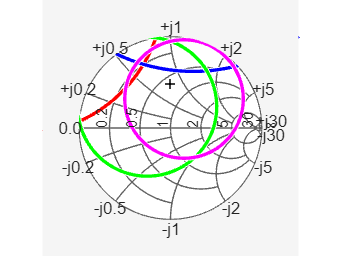

h = smithplot(ZL,'Color','black','LineStyle','-.','LineWidth',1);

h.Marker = {'+','h'}

h =   smithplot with properties:

         Data: {[0.0000 + 0.4844i]  [1.1189 + 0.5882i]}
    Frequency: {[]  []}

   Show all properties, methods
